clear ;
close all;

tic
load ryan3_data.mat
toc 

Elapsed time is 1.351235 seconds.


generate_model = true

generate_model = logical
   1


if generate_model == false
    load ryan3_model_CC_RUL.mat
end

%generate_model = false
% https://kr.mathworks.com/help/matlab/ref/load.html
%load('ryan3_gen_data.mat','battery_dataset')


# 선형회귀 모델 생성

if generate_model
    
tic
mdl_Ic_RUL = fitlm(x_trainValid_Ic_RUL,y_trainValid_Ic_RUL)
toc

ryan3_model_chargeCurrent_RUL_desc = 'ryan3_model_gen_CC_RUL';
save('ryan3_model_CC_RUL.mat','ryan3_model_chargeCurrent_RUL_desc')
save('ryan3_model_CC_RUL.mat','mdl_Ic_RUL')

end

mdl_Ic_RUL = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   _________    _________    _______    ___________

    (Intercept)      0.35169    0.0097665      36.01    2.7133e-279
    x1             -0.047798     0.014404    -3.3185     0.00090601
    x2             -0.032413     0.018185    -1.7824       0.074688
    x3              -0.21615     0.017472    -12.371     4.3618e-35
    x4               0.16227     0.014826     10.945     7.7348e-28
    x5              -0.21989     0.019736    -11.141     8.7442e-29
    x6          

Elapsed time is 0.331108 seconds.


# 선형회귀 예측

coeff = mdl_Ic_RUL.Coefficients.Estimate

coeff =     0.3517
   -0.0478
   -0.0324
   -0.2161
    0.1623
   -0.2199
   -0.0569
   -0.0843
    0.2115
   -0.2393


x_trainValid_Ic_RUL(1,:)

ans =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid_Ic_RUL*coeff(2:21)+coeff(1)

yhat =     0.4490
    0.4577
    0.4475
    0.4580
    0.4433
    0.4403
    0.4403
    0.4385
    0.4368
    0.4355


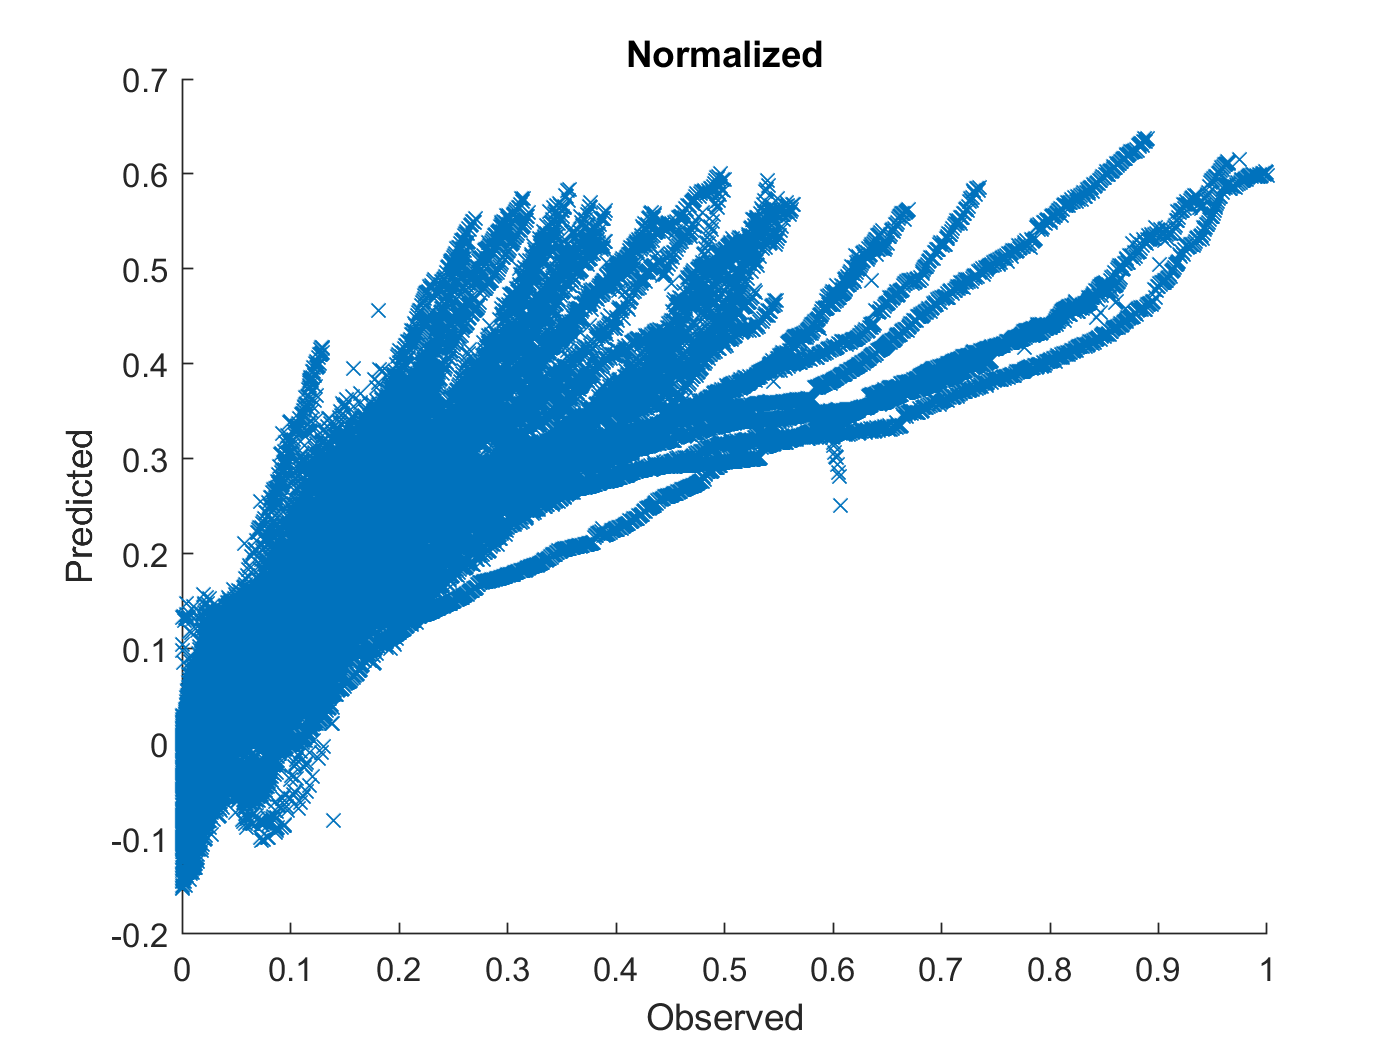

figure
hold on
plot(y_trainValid_Ic_RUL,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

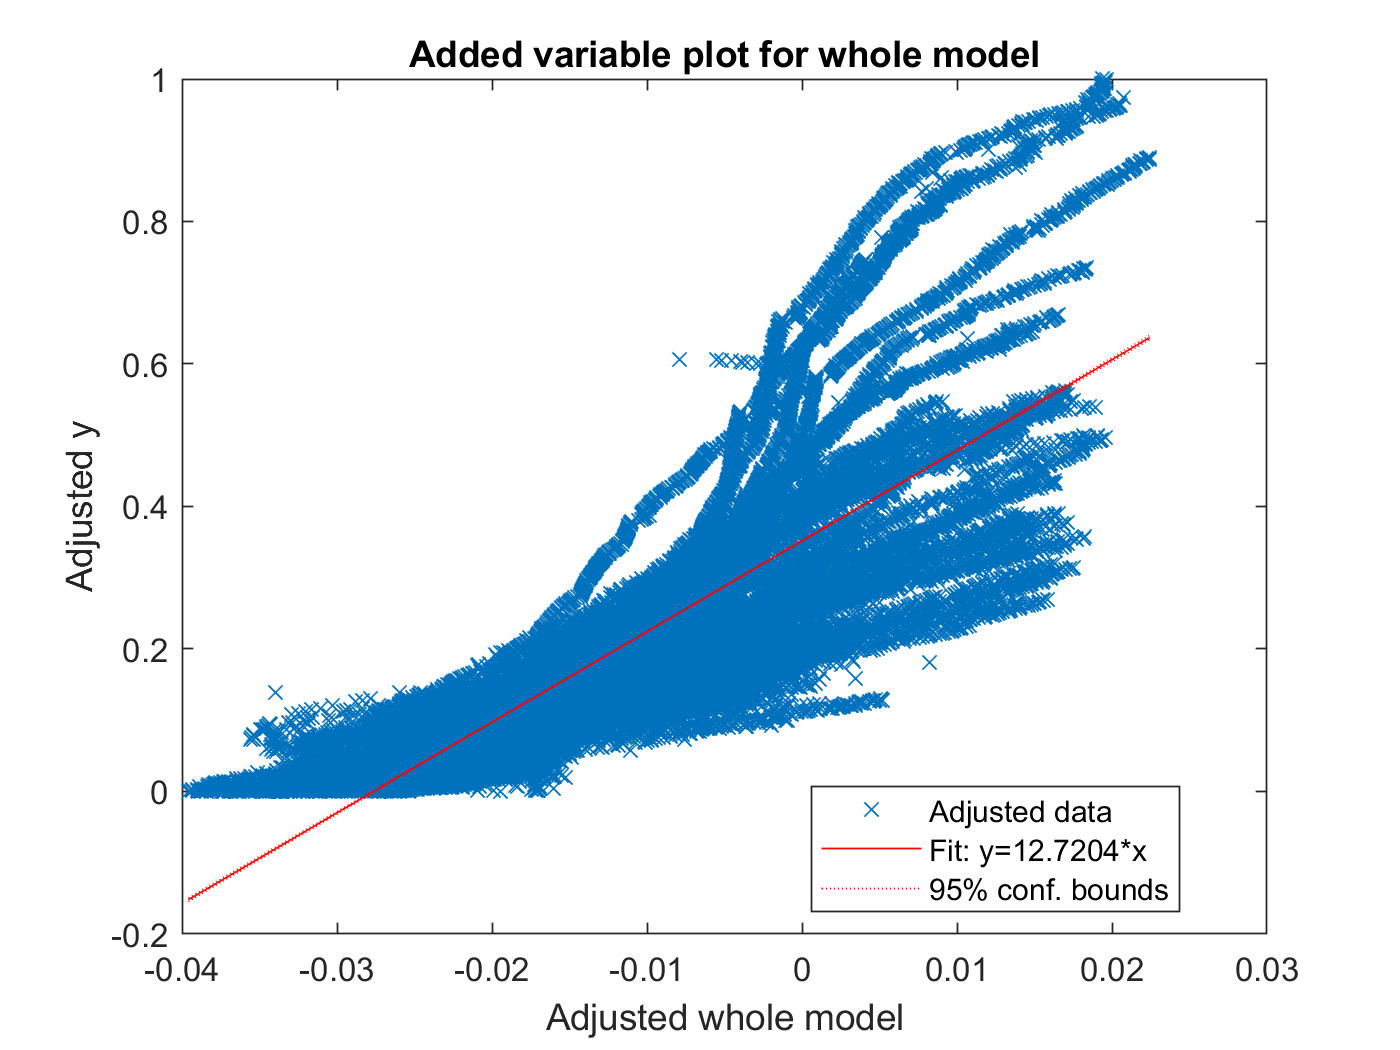


%capHat = Ic(1)

plot(mdl_Ic_RUL)

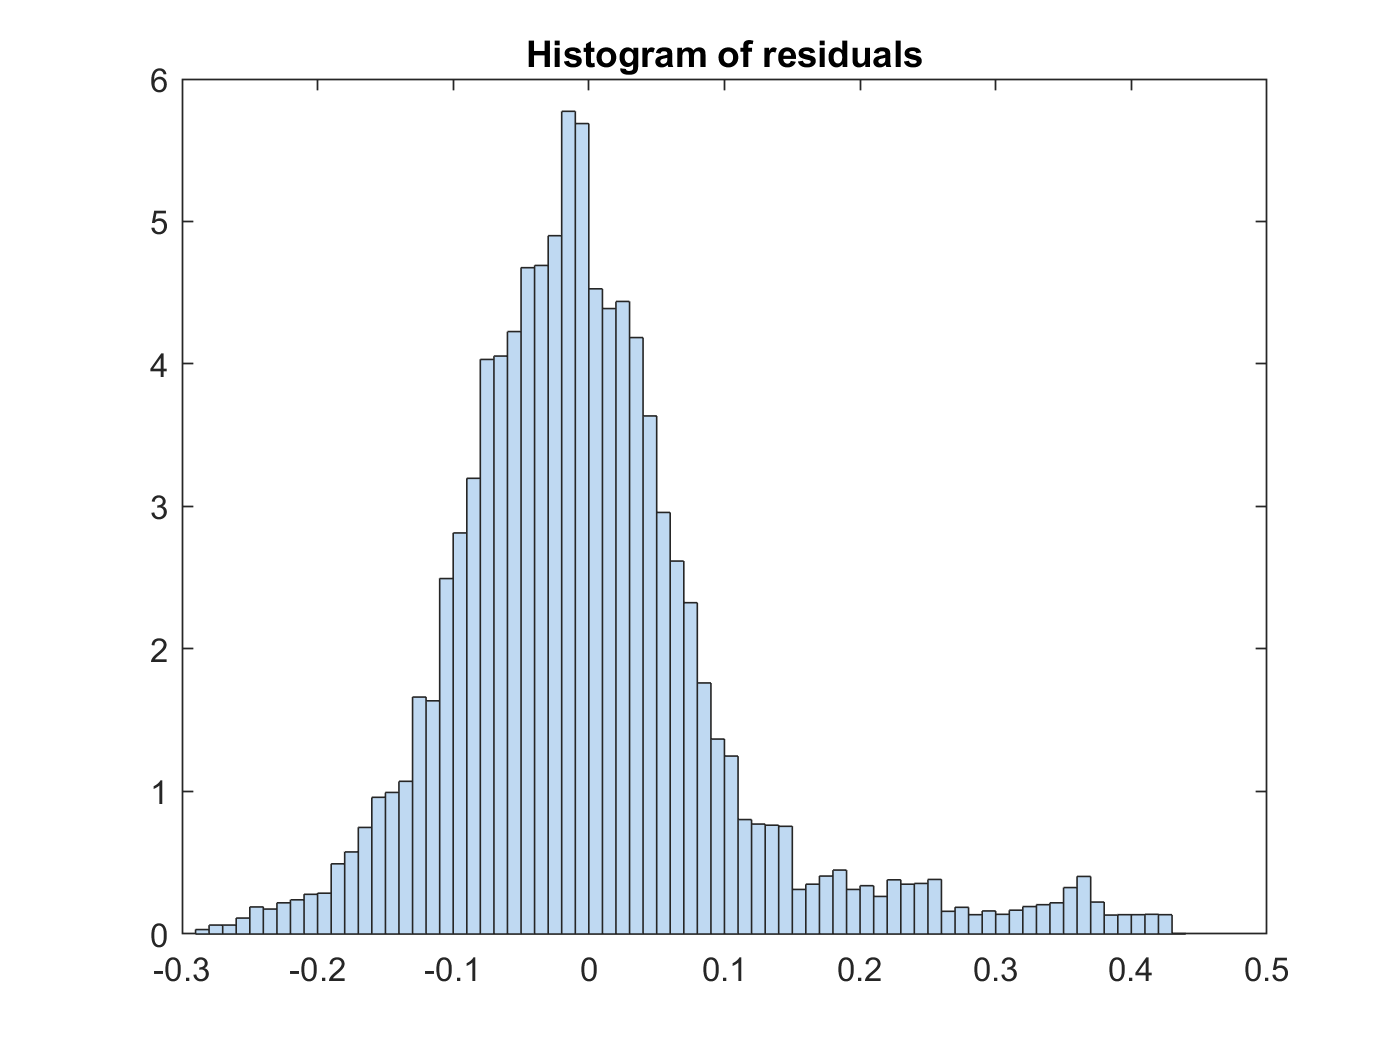

plotResiduals(mdl_Ic_RUL)




% yfit = predict(mdl_Ic_RUL,Ic)
yfit = predict(mdl_Ic_RUL,x_trainValid_Ic_RUL)

yfit =     0.4490
    0.4577
    0.4475
    0.4580
    0.4433
    0.4403
    0.4403
    0.4385
    0.4368
    0.4355


yfit_test = predict(mdl_Ic_RUL,x_test_Ic_RUL)

yfit_test =     0.3780
    0.3759
    0.3743
    0.3705
    0.3698
    0.3690
    0.3657
    0.3647
    0.3633
    0.3602




y= y_trainValid_Ic_RUL

y =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test_Ic_RUL

y_test_Ic_RUL =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


# denormaize

yfit = yfit * yrate_Ic_RUL + ymin_Ic_RUL;
y = y * yrate_Ic_RUL + ymin_Ic_RUL;
yfit_test = yfit_test * yrate_Ic_RUL + ymin_Ic_RUL;

MAE = mean(abs(yfit-y))

MAE = 87.2495

adjMAE = MAE/range(y)

adjMAE = 0.0746

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.4276
    0.4265
    0.4256
    0.4245
    0.4236
    0.4226
    0.4216
    0.4206
    0.4196
    0.4186


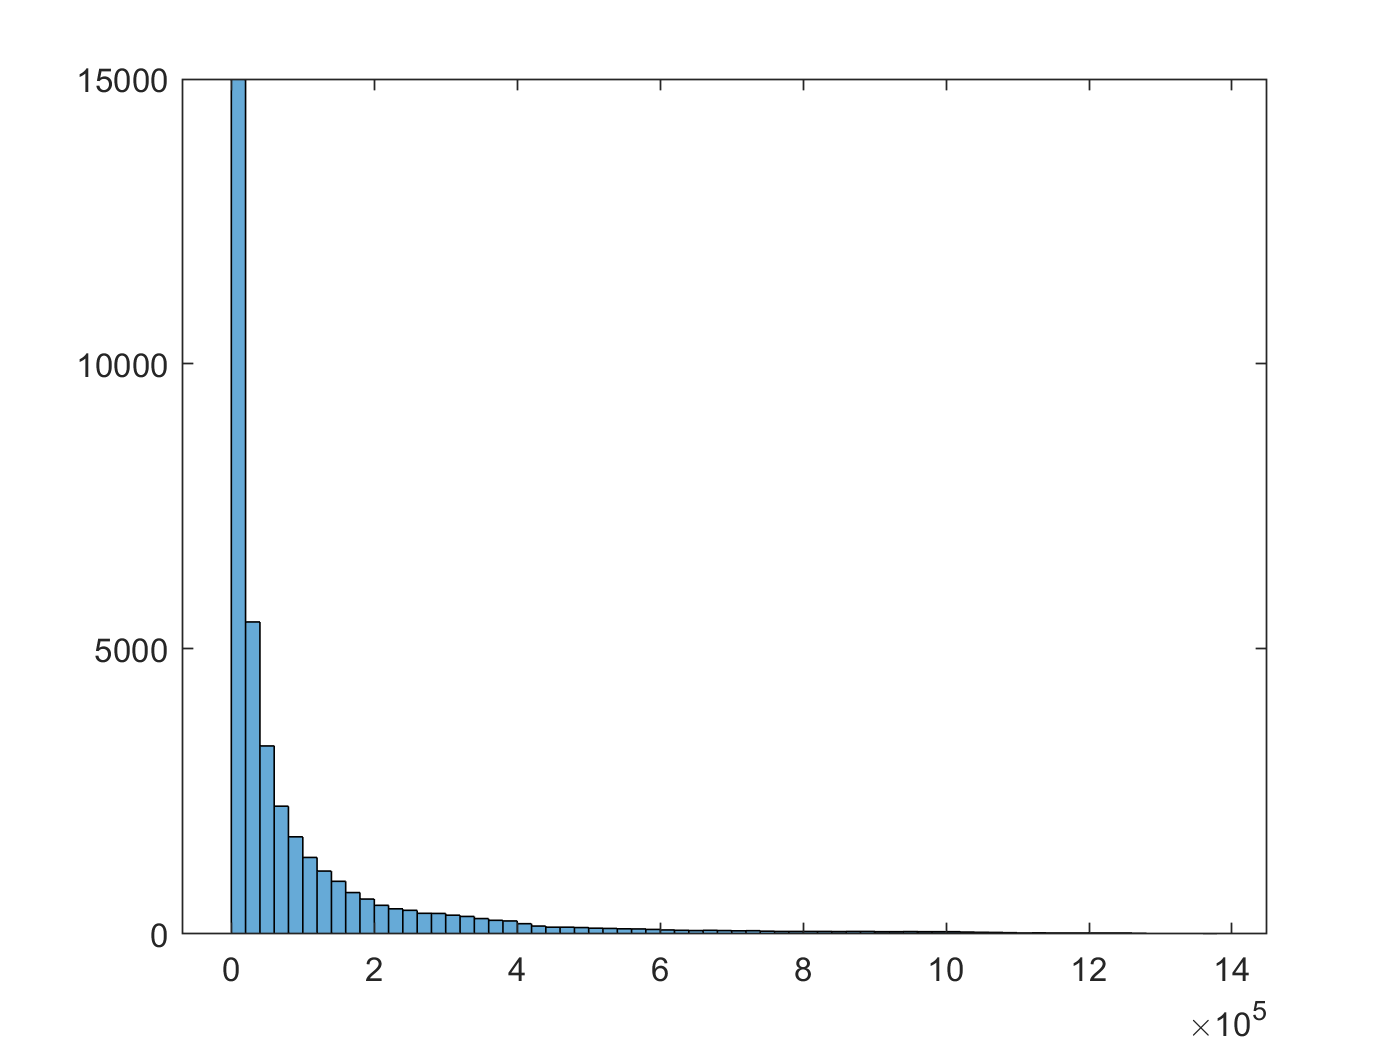

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 327.7725

y_diff = horzcat(y,(y-yfit))

y_diff = 	1.0e+03 *

    0.4280   -0.0983
    0.4270   -0.1095
    0.4260   -0.0986
    0.4250   -0.1119
    0.4240   -0.0956
    0.4230   -0.0931
    0.4220   -0.0941
    0.4210   -0.0931
    0.4200   -0.0921
    0.4190   -0.0916


y_diff_percentage = abs(y-yfit)./y.*100

y_diff_percentage = 	1.0e+04 *

    0.0023
    0.0026
    0.0023
    0.0026
    0.0023
    0.0022
    0.0022
    0.0022
    0.0022
    0.0022


length(y_diff_percentage)

ans = 38367

y_diff_percentage_avg = sum(y_diff_percentage)/length(y_diff_percentage)

y_diff_percentage_avg = 112.6278


(Y_test_Ic_RUL - yfit_test) 

ans =  -127.2287
 -125.7979
 -124.9152
 -121.4400
 -121.6311
 -121.7509
 -118.9089
 -118.7086
 -118.0507
 -115.4700


RMSE_test = sqrt(mean((Y_test_Ic_RUL - yfit_test).^2))

RMSE_test = 125.3460

y_diff_test = horzcat(Y_test_Ic_RUL,(Y_test_Ic_RUL-yfit_test))

y_diff_test = 	1.0e+03 *

    0.3160   -0.1272
    0.3150   -0.1258
    0.3140   -0.1249
    0.3130   -0.1214
    0.3120   -0.1216
    0.3110   -0.1218
    0.3100   -0.1189
    0.3090   -0.1187
    0.3080   -0.1181
    0.3070   -0.1155


y_diff_test_percentage = abs(Y_test_Ic_RUL-yfit_test)./Y_test_Ic_RUL.*100

y_diff_test_percentage = 	1.0e+04 *

    0.0040
    0.0040
    0.0040
    0.0039
    0.0039
    0.0039
    0.0038
    0.0038
    0.0038
    0.0038


y_diff_test_percentage_avg = sum(y_diff_test_percentage)/length(y_diff_test_percentage)

y_diff_test_percentage_avg = 110.0737

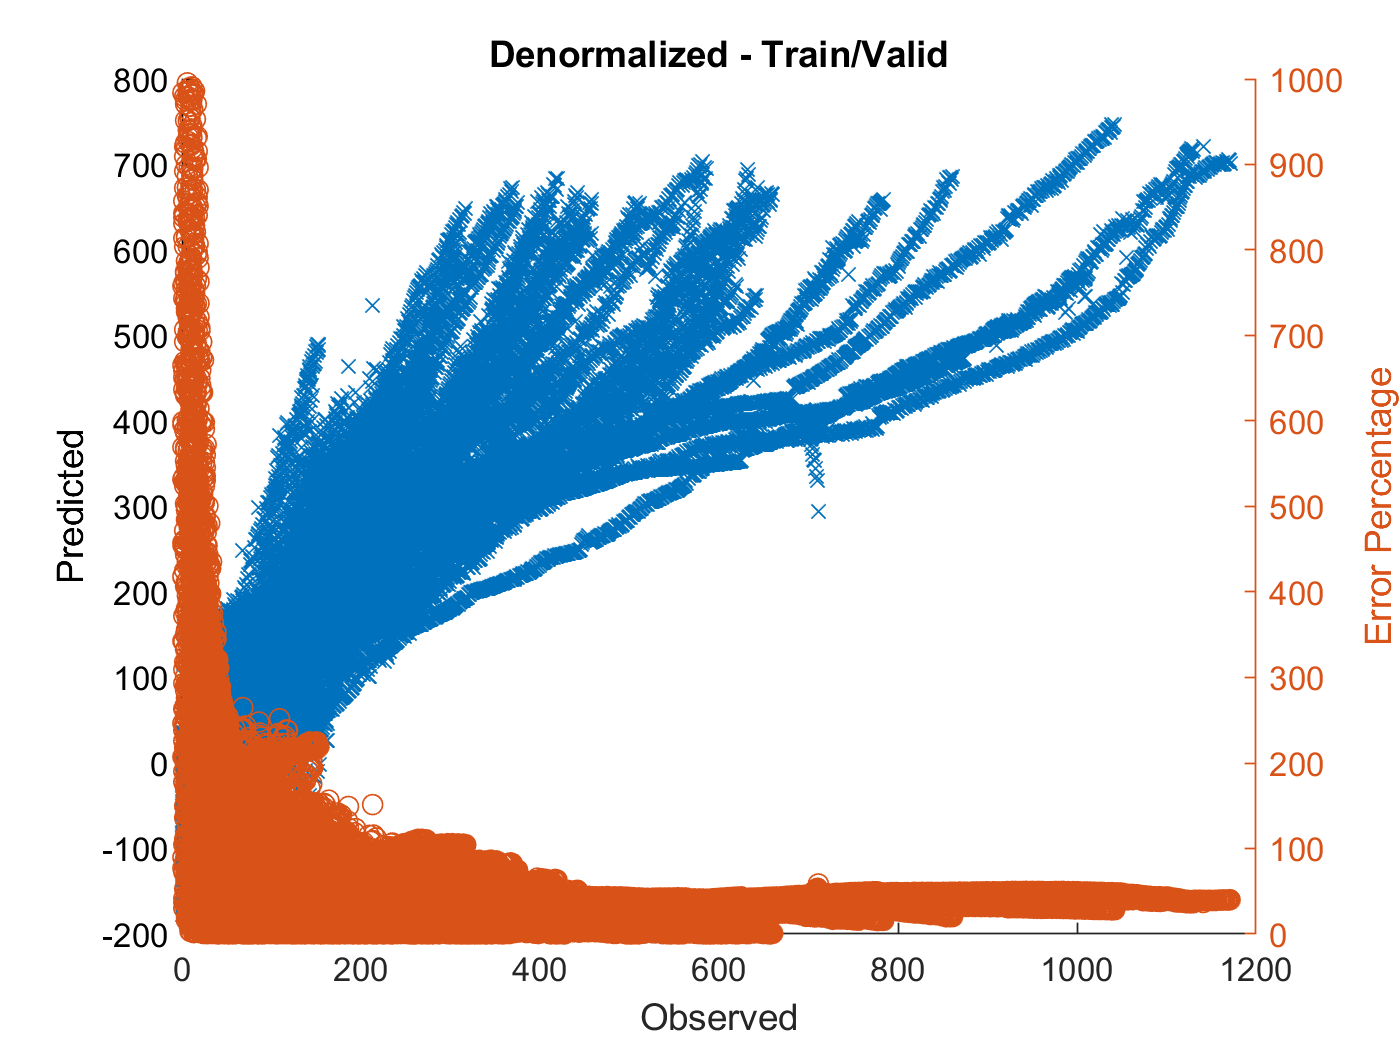


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")

yyaxis right
ylabel('Error Percentage')
plot(y,y_diff_percentage,'o');
ylim([0 1000])

hold off
title 'Denormalized - Train/Valid'

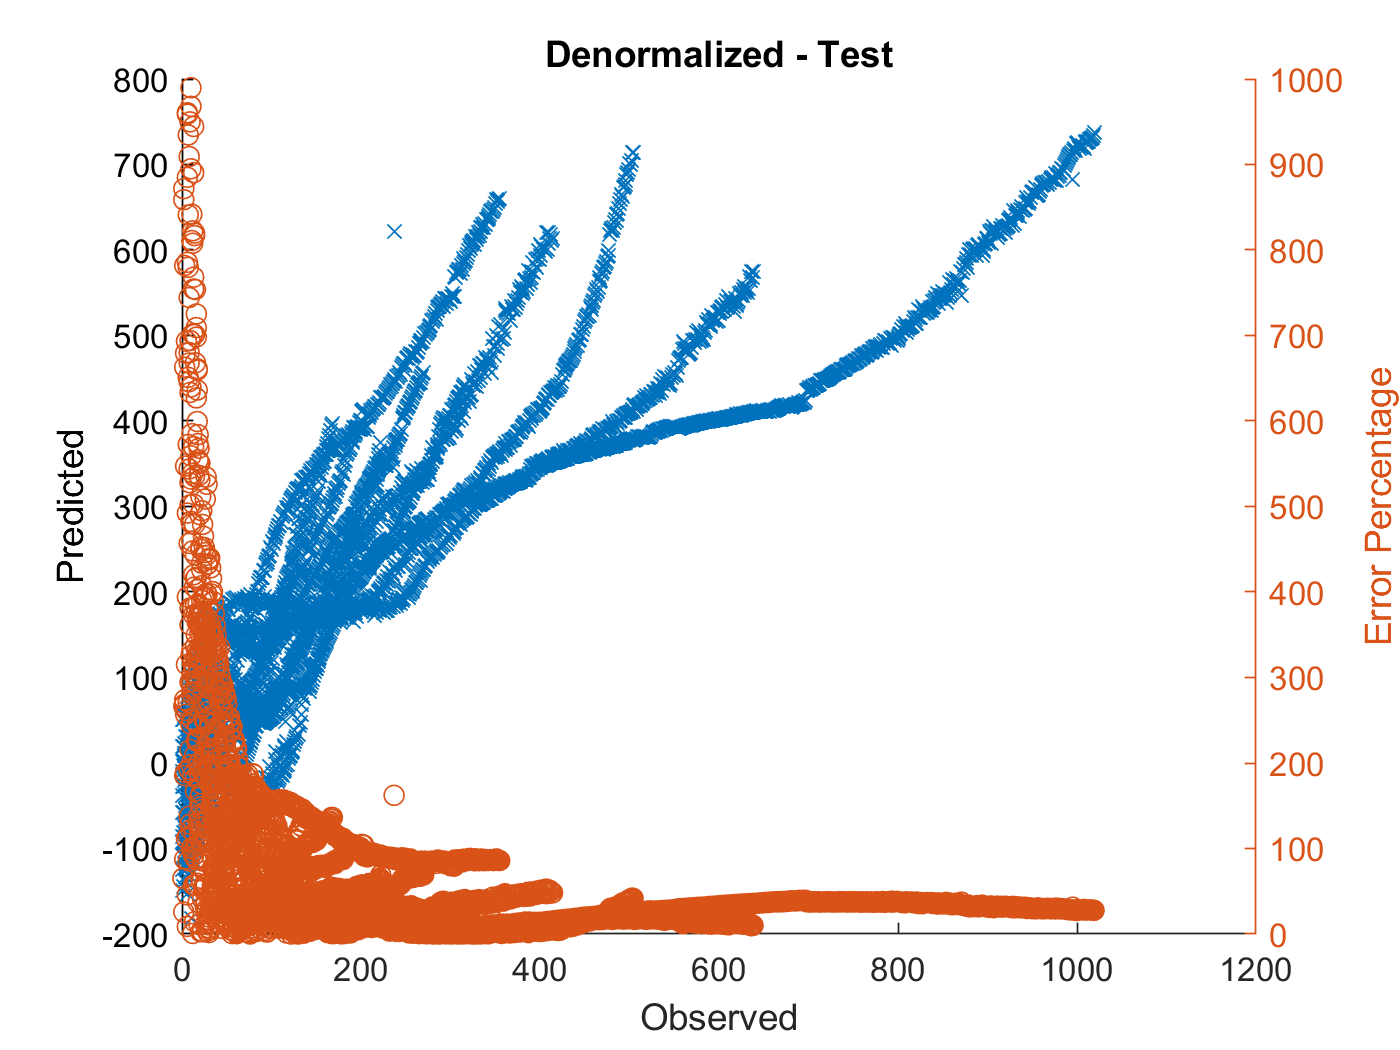


figure
hold on
plot(Y_test_Ic_RUL,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")

yyaxis right
ylabel('Error Percentage')
plot(Y_test_Ic_RUL,y_diff_test_percentage,'o');
ylim([0 1000])

hold off
title 'Denormalized - Test'

%xlim([0 1200]), ylim([0 1200])

% 테스트 셋에서는 예측이 전혀 안된다.


# 머신러닝을 위한 기본 설정

epoc_count = 5;
epoc_count_lstm = 3;
%epoc_count = 10; % 시간이 너무 오래 걸린다.
cc_input_size = 20;

# FNN 모델 생성

- FNN1 - 1 layer

if generate_model
netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainAll;
netFNN1_1.divideParam.valInd = idxValidAll;
netFNN1_1.divideParam.testInd = idxTestAll; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
[netFNN1_1, tr] = train(netFNN1_1, xnorm_Ic_RUL', ynorm_Ic_RUL', 'useparallel',  'yes');
toc
%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = idxTrainAll;
netFNN1_2.divideParam.valInd = idxValidAll;
netFNN1_2.divideParam.testInd = idxTestAll; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_2 = train(netFNN1_2, xnorm_Ic_RUL', ynorm_Ic_RUL', 'useparallel',  'yes');
toc


netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = idxTrainAll;
netFNN1_3.divideParam.valInd = idxValidAll;
netFNN1_3.divideParam.testInd = idxTestAll; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_3 = train(netFNN1_3, xnorm_Ic_RUL', ynorm_Ic_RUL', 'useparallel',  'yes');
toc


netFNN2_1 = feedforwardnet([20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = idxTrainAll;
netFNN2_1.divideParam.valInd = idxValidAll;
netFNN2_1.divideParam.testInd = idxTestAll; 

netFNN2_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
tic
[netFNN2_1, tr2] = train(netFNN2_1, xnorm_Ic_RUL', ynorm_Ic_RUL', 'useparallel',  'yes');
toc
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([50,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = idxTrainAll;
netFNN2_2.divideParam.valInd = idxValidAll;
netFNN2_2.divideParam.testInd = idxTestAll; 

netFNN2_2.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
tic
netFNN2_2 = train(netFNN2_1, xnorm_Ic_RUL', ynorm_Ic_RUL', 'useparallel',  'yes');
toc
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = idxTrainAll;
netFNN3_1.divideParam.valInd = idxValidAll;
netFNN3_1.divideParam.testInd = idxTestAll; 

netFNN3_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
tic
netFNN3_1 = train(netFNN3_1, xnorm_Ic_RUL', ynorm_Ic_RUL', 'useparallel',  'yes');
toc
%view(netFNN3_1)


netFNN4_1 = feedforwardnet([50,20,10,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = idxTrainAll;
netFNN4_1.divideParam.valInd = idxValidAll;
netFNN4_1.divideParam.testInd = idxTestAll; 

netFNN4_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
tic
netFNN4_1 = train(netFNN4_1, xnorm_Ic_RUL', ynorm_Ic_RUL', 'useparallel',  'yes');
toc
%view(netFNN3_1)


netFNN5_1 = feedforwardnet([50,20,10,5,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = idxTrainAll;
netFNN5_1.divideParam.valInd = idxValidAll;
netFNN5_1.divideParam.testInd = idxTestAll; 

netFNN5_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
tic
netFNN5_1 = train(netFNN5_1, xnorm_Ic_RUL', ynorm_Ic_RUL', 'useparallel',  'yes');
toc
%view(netFNN3_1)


save('ryan3_model_CC_RUL.mat','netFNN1_1' ,'-append')
save('ryan3_model_CC_RUL.mat','netFNN1_2' ,'-append')
save('ryan3_model_CC_RUL.mat','netFNN1_3' ,'-append')
save('ryan3_model_CC_RUL.mat','netFNN2_1' ,'-append')
save('ryan3_model_CC_RUL.mat','netFNN2_2' ,'-append')
save('ryan3_model_CC_RUL.mat','netFNN3_1' ,'-append')
save('ryan3_model_CC_RUL.mat','netFNN4_1' ,'-append')
save('ryan3_model_CC_RUL.mat','netFNN5_1' ,'-append')

end

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 2.403354 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 4.994493 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 89.134101 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 8.339757 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 6.802760 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 168.985582 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 186.073251 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 144.209941 seconds.


# FNN 예측


pFNN1_1 = netFNN1_1(xnorm_Ic_RUL(idxTestAll, :)');
pFNN1_2 = netFNN1_2(xnorm_Ic_RUL(idxTestAll, :)');
pFNN1_3 = netFNN1_3(xnorm_Ic_RUL(idxTestAll, :)');
pFNN2_1 = netFNN2_1(xnorm_Ic_RUL(idxTestAll, :)');
pFNN2_2 = netFNN2_2(xnorm_Ic_RUL(idxTestAll, :)');
pFNN3_1 = netFNN3_1(xnorm_Ic_RUL(idxTestAll, :)');
pFNN4_1 = netFNN4_1(xnorm_Ic_RUL(idxTestAll, :)');
pFNN5_1 = netFNN5_1(xnorm_Ic_RUL(idxTestAll, :)');

ytest = ynorm_Ic_RUL(idxTestAll, :)*yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_1_hat = pFNN1_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_2_hat = pFNN1_2 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_3_hat = pFNN1_3 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN2_1_hat = pFNN2_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN2_2_hat = pFNN2_2 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN3_1_hat = pFNN3_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN4_1_hat = pFNN4_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN5_1_hat = pFNN5_1 * yrate_Ic_RUL + ymin_Ic_RUL;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 104.5561

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 94.7680

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 102.0190

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 90.0003

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 93.6945

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 124.7426

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 120.7591

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 109.2205



y_test_diff_percentage_FNN1_1_hat_avg = sum(abs(Y_test_Ic_RUL'-pFNN1_1_hat)./Y_test_Ic_RUL'.*100)/length(abs(Y_test_Ic_RUL'-pFNN1_1_hat)./Y_test_Ic_RUL')

y_test_diff_percentage_FNN1_1_hat_avg = 71.4917

y_test_diff_percentage_FNN1_2_hat_avg = sum(abs(Y_test_Ic_RUL'-pFNN1_2_hat)./Y_test_Ic_RUL'.*100)/length(abs(Y_test_Ic_RUL'-pFNN1_2_hat)./Y_test_Ic_RUL')

y_test_diff_percentage_FNN1_2_hat_avg = 55.2692

y_test_diff_percentage_FNN1_3_hat_avg = sum(abs(Y_test_Ic_RUL'-pFNN1_3_hat)./Y_test_Ic_RUL'.*100)/length(abs(Y_test_Ic_RUL'-pFNN1_3_hat)./Y_test_Ic_RUL')

y_test_diff_percentage_FNN1_3_hat_avg = 71.6920

y_test_diff_percentage_FNN2_1_hat_avg = sum(abs(Y_test_Ic_RUL'-pFNN2_1_hat)./Y_test_Ic_RUL'.*100)/length(abs(Y_test_Ic_RUL'-pFNN2_1_hat)./Y_test_Ic_RUL')

y_test_diff_percentage_FNN2_1_hat_avg = 44.8672

y_test_diff_percentage_FNN2_2_hat_avg = sum(abs(Y_test_Ic_RUL'-pFNN2_2_hat)./Y_test_Ic_RUL'.*100)/length(abs(Y_test_Ic_RUL'-pFNN2_2_hat)./Y_test_Ic_RUL')

y_test_diff_percentage_FNN2_2_hat_avg = 43.1813

y_test_diff_percentage_FNN3_1_hat_avg = sum(abs(Y_test_Ic_RUL'-pFNN3_1_hat)./Y_test_Ic_RUL'.*100)/length(abs(Y_test_Ic_RUL'-pFNN3_1_hat)./Y_test_Ic_RUL')

y_test_diff_percentage_FNN3_1_hat_avg = 61.2704

y_test_diff_percentage_FNN4_1_hat_avg = sum(abs(Y_test_Ic_RUL'-pFNN4_1_hat)./Y_test_Ic_RUL'.*100)/length(abs(Y_test_Ic_RUL'-pFNN4_1_hat)./Y_test_Ic_RUL')

y_test_diff_percentage_FNN4_1_hat_avg = 95.8984

y_test_diff_percentage_FNN5_1_hat_avg = sum(abs(Y_test_Ic_RUL'-pFNN5_1_hat)./Y_test_Ic_RUL'.*100)/length(abs(Y_test_Ic_RUL'-pFNN5_1_hat)./Y_test_Ic_RUL')

y_test_diff_percentage_FNN5_1_hat_avg = 40.1844

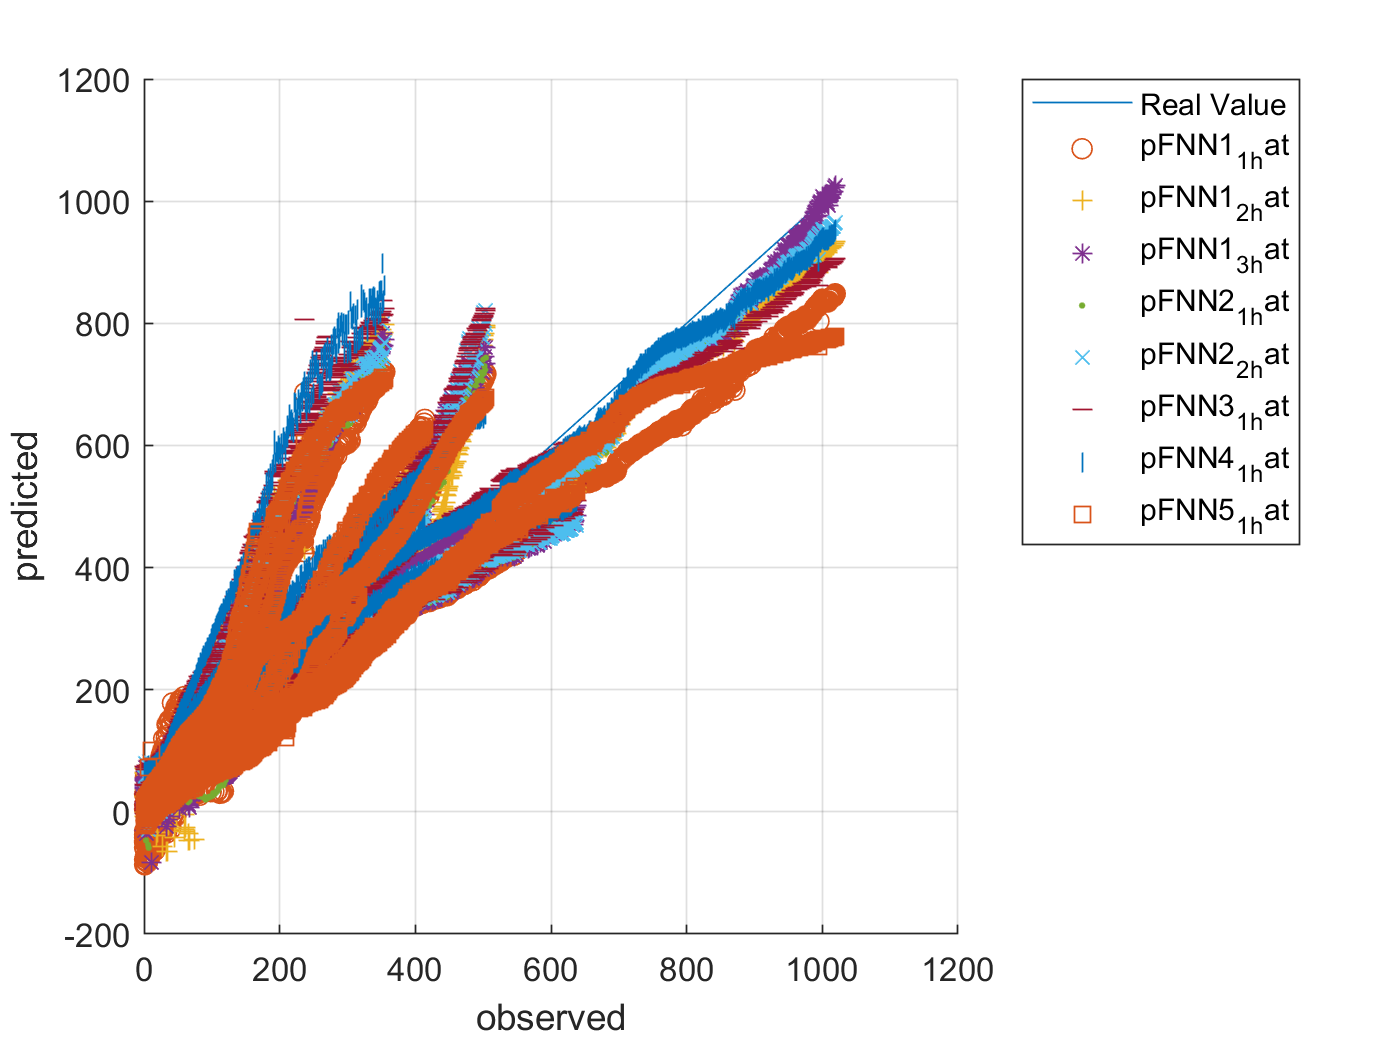



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')


y_test_diff_percentage_FNN1_2_hat = abs(Y_test_Ic_RUL'-pFNN1_2_hat)./Y_test_Ic_RUL'.*100

y_test_diff_percentage_FNN1_2_hat = 	1.0e+03 *

    0.0308    0.0309    0.0311    0.0310    0.0313    0.0317    0.0315    0.0313    0.0310    0.0304    0.0301    0.0300    0.0295    0.0298    0.0305    0.0303    0.0287    0.0291    0.0282    0.0277    0.0270    0.0290    0.0313    0.0326    0.0331    0.0333    0.0330    0.0320    0.0303    0.0272    0.0249    0.0251    0.0244    0.0244    0.0242    0.0242    0.0238    0.0244    0.0241    0.0244    0.0247    0.0243    0.0246    0.0246    0.0247    0.0247    0.0249    0.0250    0.0247    0.0252


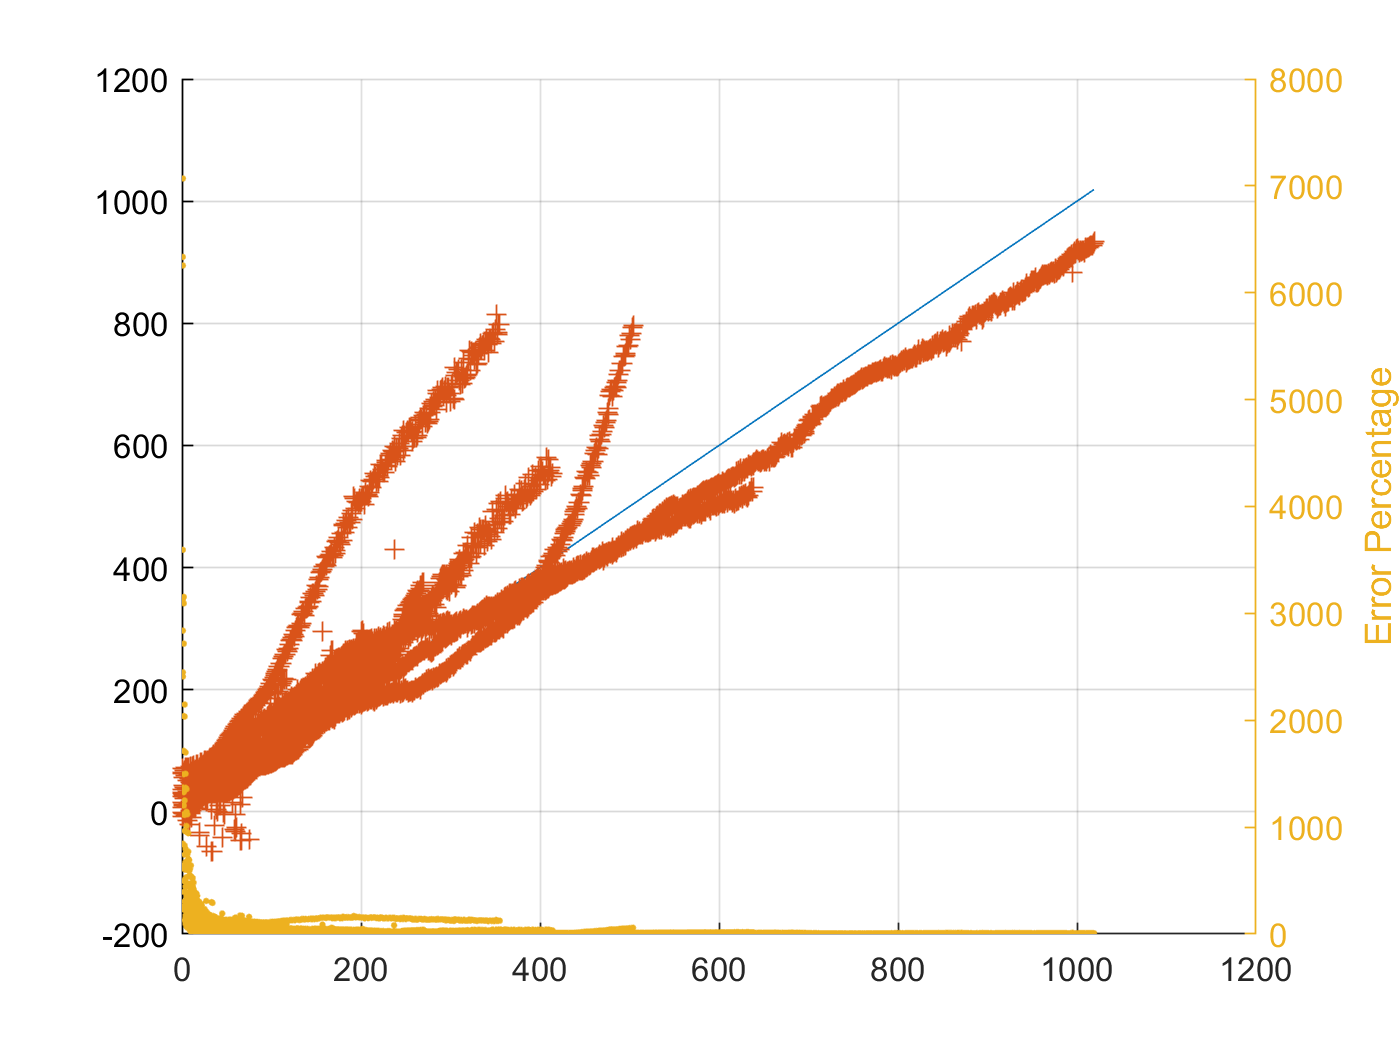

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_2_hat,'+')

yyaxis right
ylabel('Error Percentage')
plot(ytest,y_test_diff_percentage_FNN1_2_hat,'.')

hold off

pFNN1_1_self = netFNN1_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN1_2_self = netFNN1_2(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN1_3_self = netFNN1_3(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN2_1_self = netFNN2_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN2_2_self = netFNN2_2(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN3_1_self = netFNN3_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN4_1_self = netFNN4_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');
pFNN5_1_self = netFNN5_1(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)');

ytrain_self = ynorm_Ic_RUL([idxTrainAll idxValidAll], :)*yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_1_self_hat = pFNN1_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_2_self_hat = pFNN1_2_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN1_3_self_hat = pFNN1_3_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN2_1_self_hat = pFNN2_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN2_2_self_hat = pFNN2_2_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN3_1_self_hat = pFNN3_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN4_1_self_hat = pFNN4_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pFNN5_1_self_hat = pFNN5_1_self * yrate_Ic_RUL + ymin_Ic_RUL;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 113.0563

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 101.8672

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 95.8571

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 95.4958

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 91.9606

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 100.2026

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 106.7543

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 110.5750

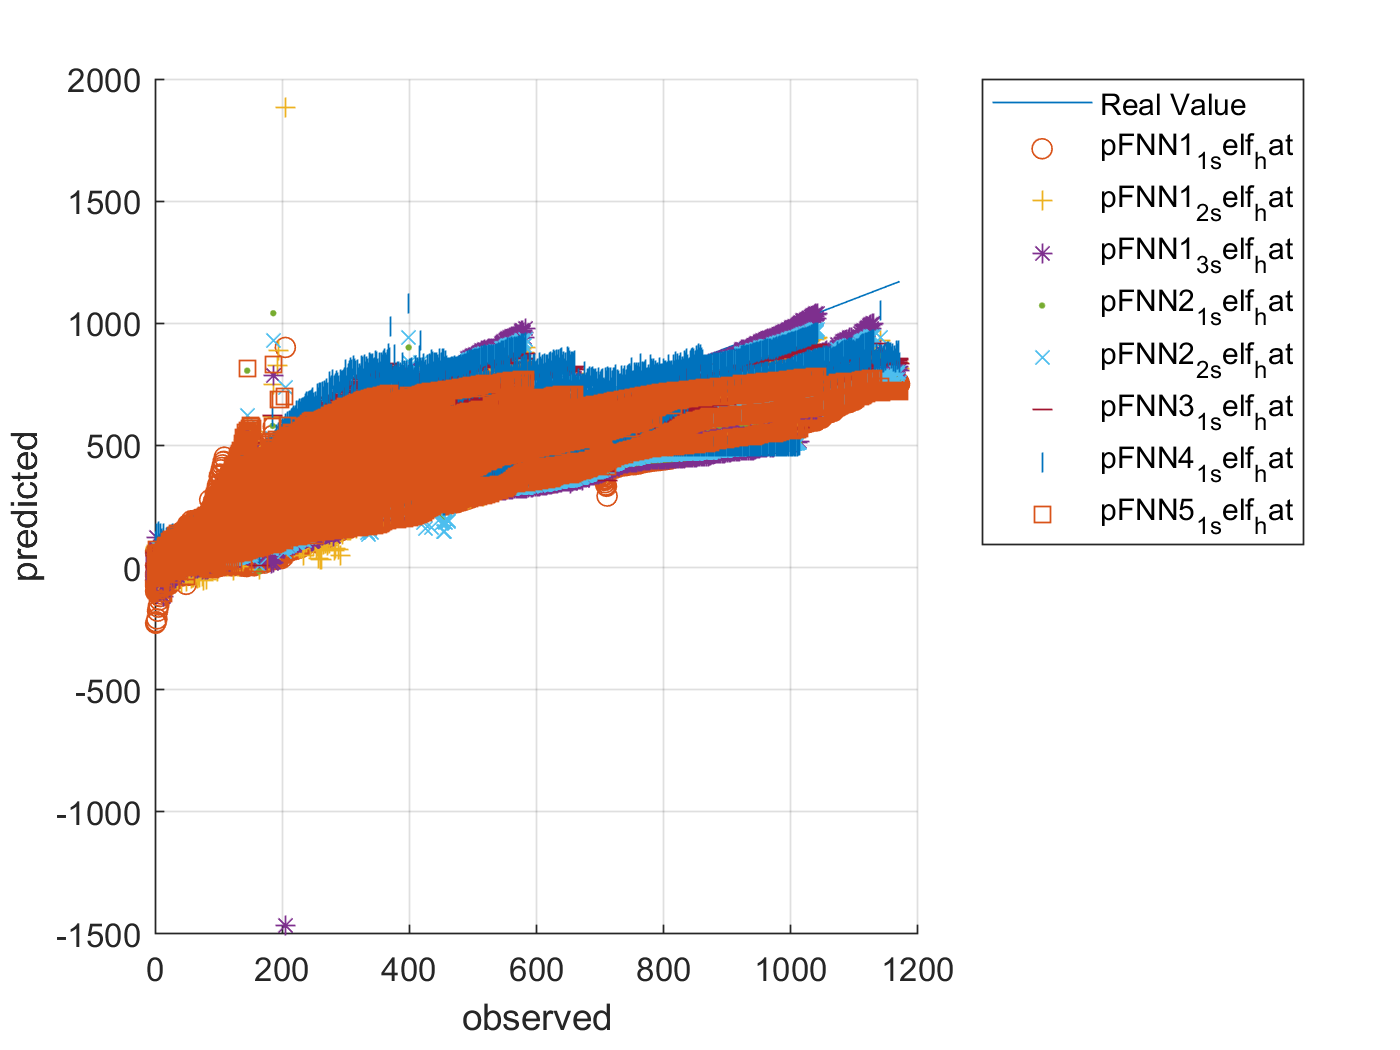



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

% For CNN
filterSize = 3;
numFilters = 32;
numFCN = 1;


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.


if generate_model

layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm_Ic_RUL', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm_Ic_RUL);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(idxTrainAll, :);
valtbl = tbl(idxValidAll, :);
testtbl = tbl(idxTestAll, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',epoc_count, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

tic
netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);
toc




- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:24 |         0.28 |         0.27 |       0.0395 |       0.0375 |          0.0010 |
|       1 |          50 |       00:00:36 |         0.15 |         0.17 |       0.0113 |       0.0148 |          0.0010 |
|       1 |         100 |       00:00:39 |         0.12 |         0.16 |       0.0069 |       0.0125 |          0.0010 |
|       1 |         150 |       00:00:45 |         0.11 |         0.15 |       0.0063 |   

Elapsed time is 1268.318698 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:21 |         0.27 |         0.27 |       0.0371 |       0.0371 |          0.0010 |
|       1 |          50 |       00:00:33 |         0.14 |         0.17 |       0.0093 |       0.0150 |          0.0010 |
|       1 |         100 |       00:00:53 |         0.15 |         0.15 |       0.0116 |       0.0116 |          0.0010 |
|       1 |         150 |       00:01:01 |         0.13 |         0.14 |       0.0089 |   

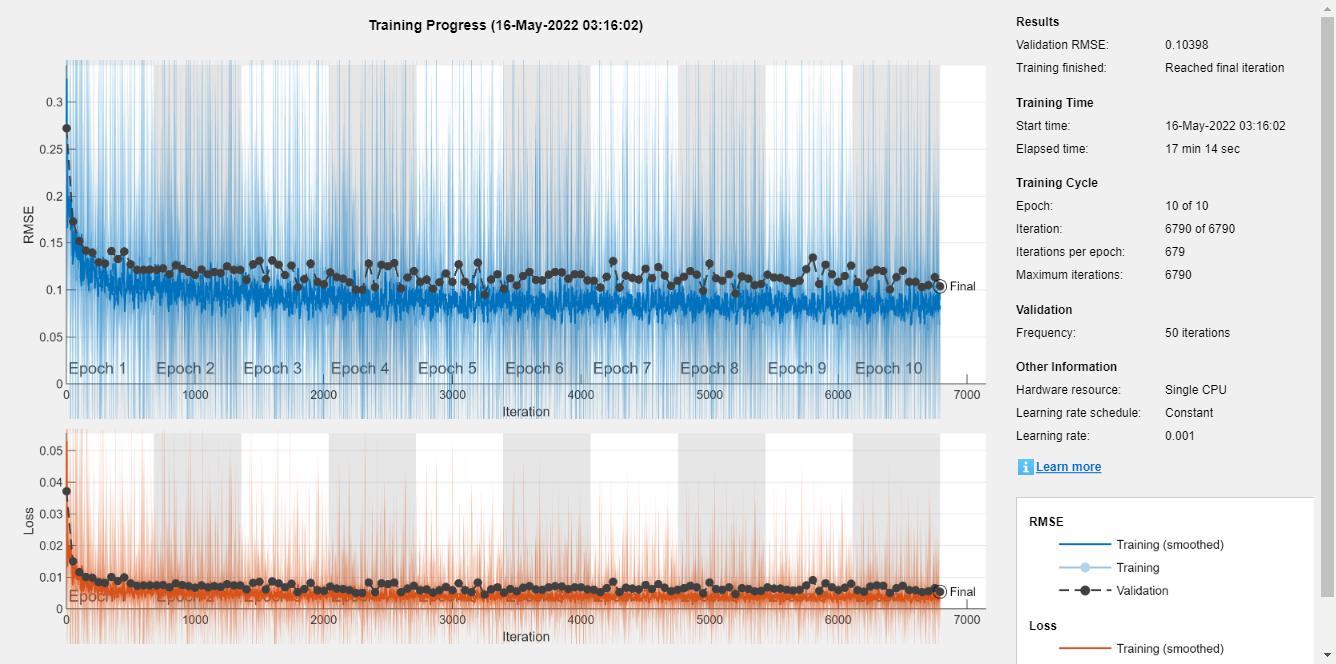

Elapsed time is 1061.492169 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.38 |         0.38 |       0.0739 |       0.0724 |          0.0010 |
|       1 |          50 |       00:00:07 |         0.13 |         0.18 |       0.0081 |       0.0170 |          0.0010 |
|       1 |         100 |       00:00:09 |         0.16 |         0.17 |       0.0125 |       0.0141 |          0.0010 |
|       1 |         150 |       00:00:10 |         0.13 |         0.16 |       0.0082 |   

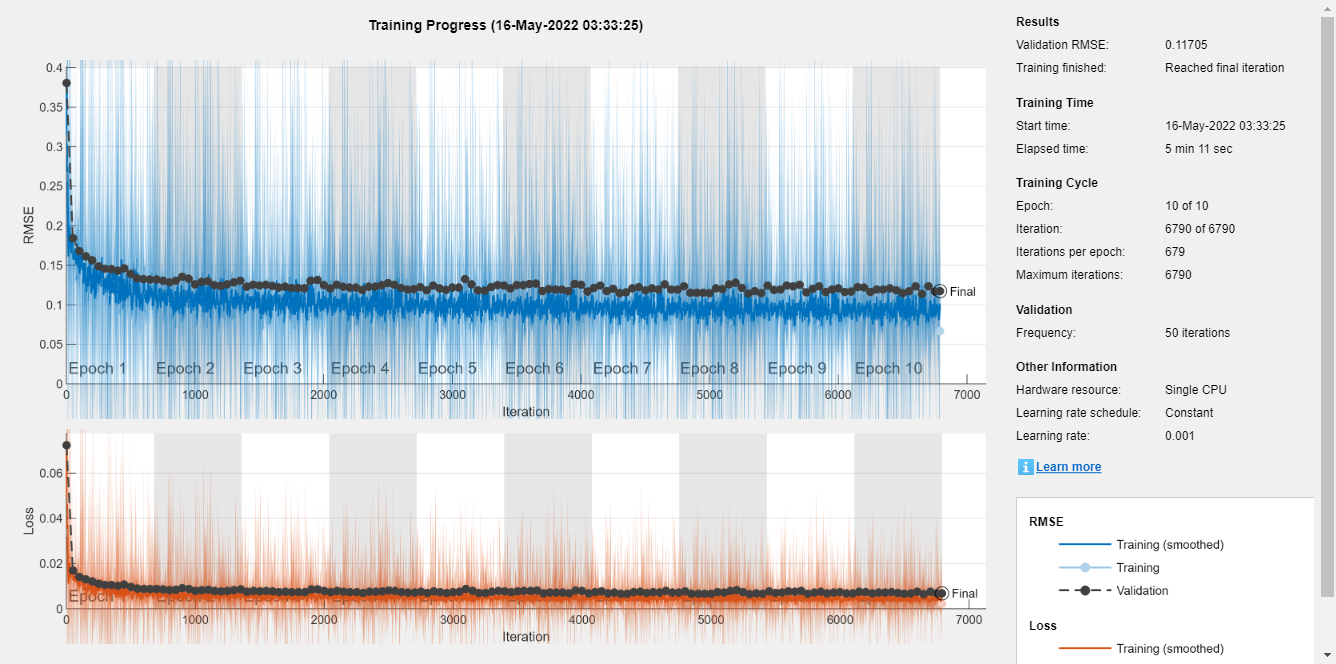

Elapsed time is 321.174464 seconds.


layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

tic
netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);
toc

layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
tic
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);
toc

%%%% 시간이 오래 걸린다. 
%{
layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);
toc

layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);
toc


figure
plot(xnorm_Ic_RUL')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm_Ic_RUL,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")
%}
%%%%%%%%%%%%%%

save('ryan3_model_CC_RUL.mat','netCNN2_1' ,'-append')
save('ryan3_model_CC_RUL.mat','netCNN2_2' ,'-append')
%save('ryan3_model_CC_RUL.mat','netCNN2_3' ,'-append')
%save('ryan3_model_CC_RUL.mat','netCNN2_4' ,'-append')
save('ryan3_model_CC_RUL.mat','netCNN1_1' ,'-append')

end


cellx = num2cell(xnorm_Ic_RUL(idxTestAll, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
%pCNN2_3 = predict(netCNN2_3, x_4d);
%pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);



ytest = ynorm_Ic_RUL(idxTestAll, :)*yrate_Ic_RUL + ymin_Ic_RUL;
pCNN2_1_hat = pCNN2_1 * yrate_Ic_RUL + ymin_Ic_RUL;
pCNN2_2_hat = pCNN2_2 * yrate_Ic_RUL + ymin_Ic_RUL;
%pCNN2_3_hat = pCNN2_3 * yrate_Ic_RUL + ymin_Ic_RUL;
%pCNN2_4_hat = pCNN2_4 * yrate_Ic_RUL + ymin_Ic_RUL;
pCNN1_1_hat = pCNN1_1 * yrate_Ic_RUL + ymin_Ic_RUL;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_1_hat = single
102.2808

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_hat = single
106.9770

%rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))
%rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))
rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN1_1_hat = single
115.0988

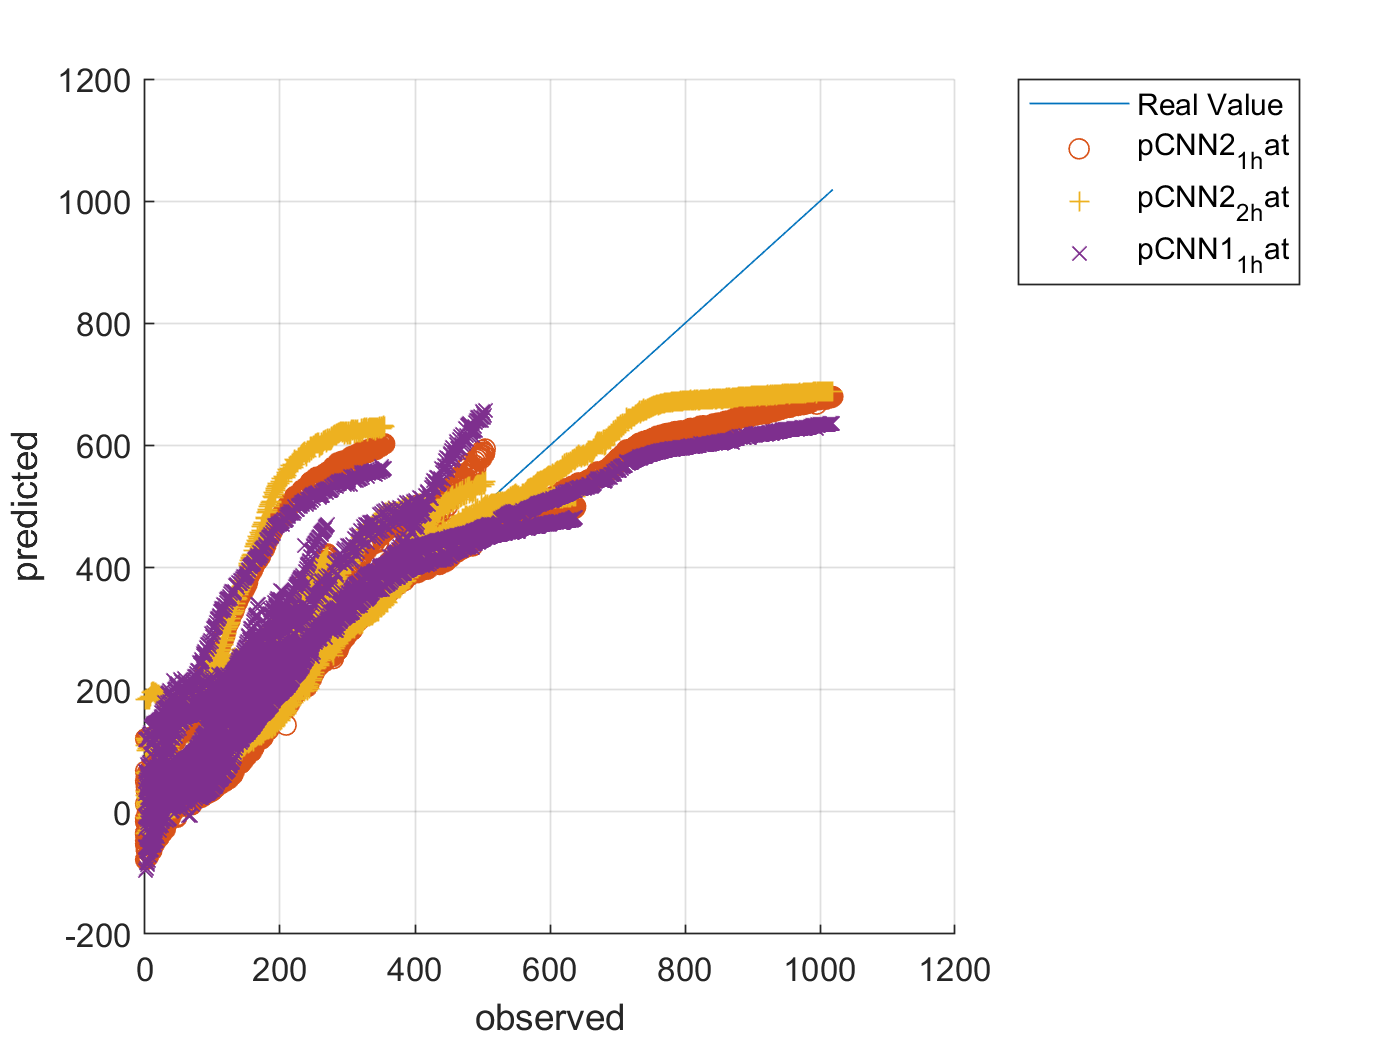




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
%plot(ytest,pCNN2_3_hat,'*')
%plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN1_1_hat','Location','northeastoutside')






cellx_self = num2cell(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
%pCNN2_3_self = predict(netCNN2_3, x_4d_self);
%pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm_Ic_RUL([idxTrainAll idxValidAll], :)*yrate_Ic_RUL + ymin_Ic_RUL;
pCNN2_1_self_hat = pCNN2_1_self * yrate_Ic_RUL + ymin_Ic_RUL;
pCNN2_2_self_hat = pCNN2_2_self * yrate_Ic_RUL + ymin_Ic_RUL;
%pCNN2_3_self_hat = pCNN2_3_self * yrate_Ic_RUL + ymin_Ic_RUL;
%pCNN2_4_self_hat = pCNN2_4_self * yrate_Ic_RUL + ymin_Ic_RUL;
pCNN1_1_self_hat = pCNN1_1_self * yrate_Ic_RUL + ymin_Ic_RUL;


rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
104.2741

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
102.2932

%rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))
%rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))
rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
113.3844

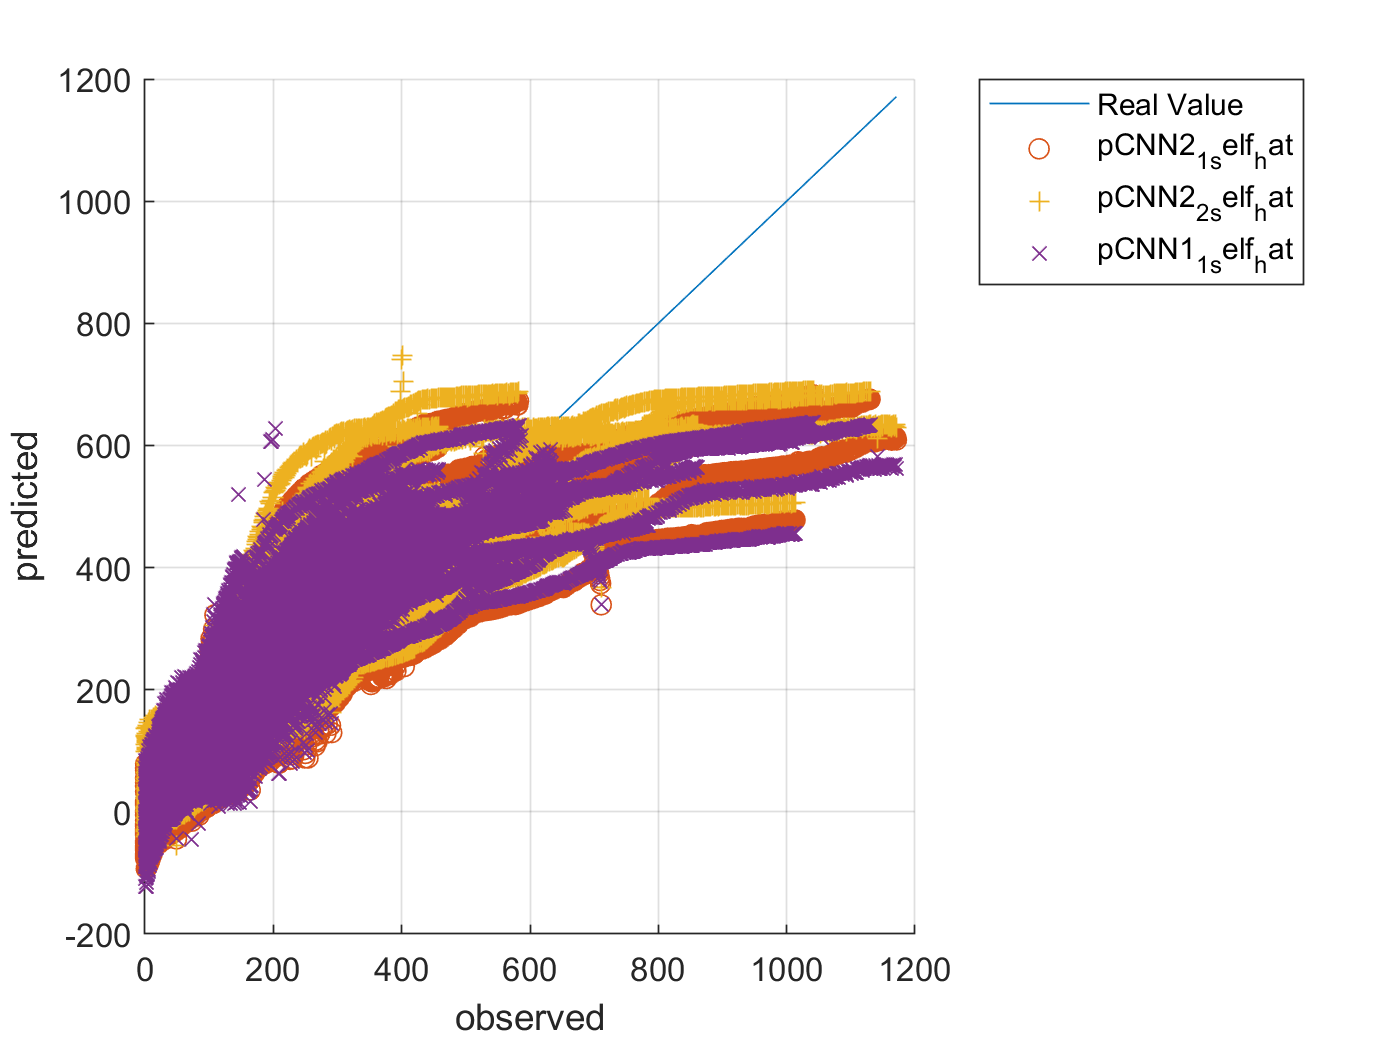




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
%plot(ytrain_self,pCNN2_3_self_hat,'*')
%plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN1_1_self_hat','Location','northeastoutside')

# LSTM

- LSTM : 1 lstm layer with 5 hidden units

cc_input_size = 20;
numHiddenUnits = 50;

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.14 |         0.20 |       0.0096 |       0.0205 |          0.0010 |
|       1 |          50 |       00:00:06 |         0.16 |         0.18 |       0.0129 |       0.0156 |          0.0010 |
|       1 |         100 |       00:00:07 |         0.18 |         0.17 |       0.0169 |       0.0141 |          0.0010 |
|       1 |         150 |       00:00:08 |         0.17 |         0.16 |       0.0146 |       0.0123 |          0.0010 |
|       

Elapsed time is 67.261310 seconds.


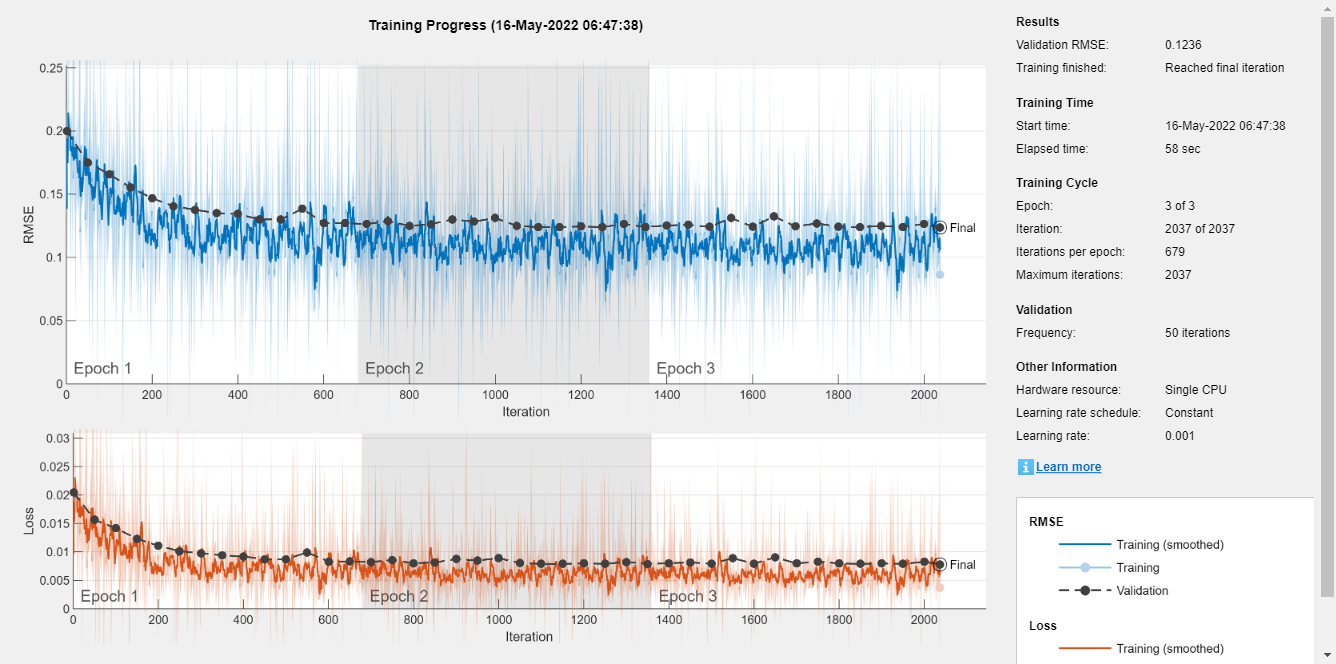

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.28 |         0.27 |       0.0394 |       0.0369 |          0.0010 |
|       1 |          50 |       00:00:07 |         0.16 |         0.19 |       0.0128 |       0.0179 |          0.0010 |
|       1 |         100 |       00:00:09 |         0.17 |         0.18 |       0.0153 |       0.0166 |          0.0010 |
|       1 |         150 |       00:00:10 |         0.10 |         0.17 |       0.0054 |       0.0141 |          0.0010 |
|       

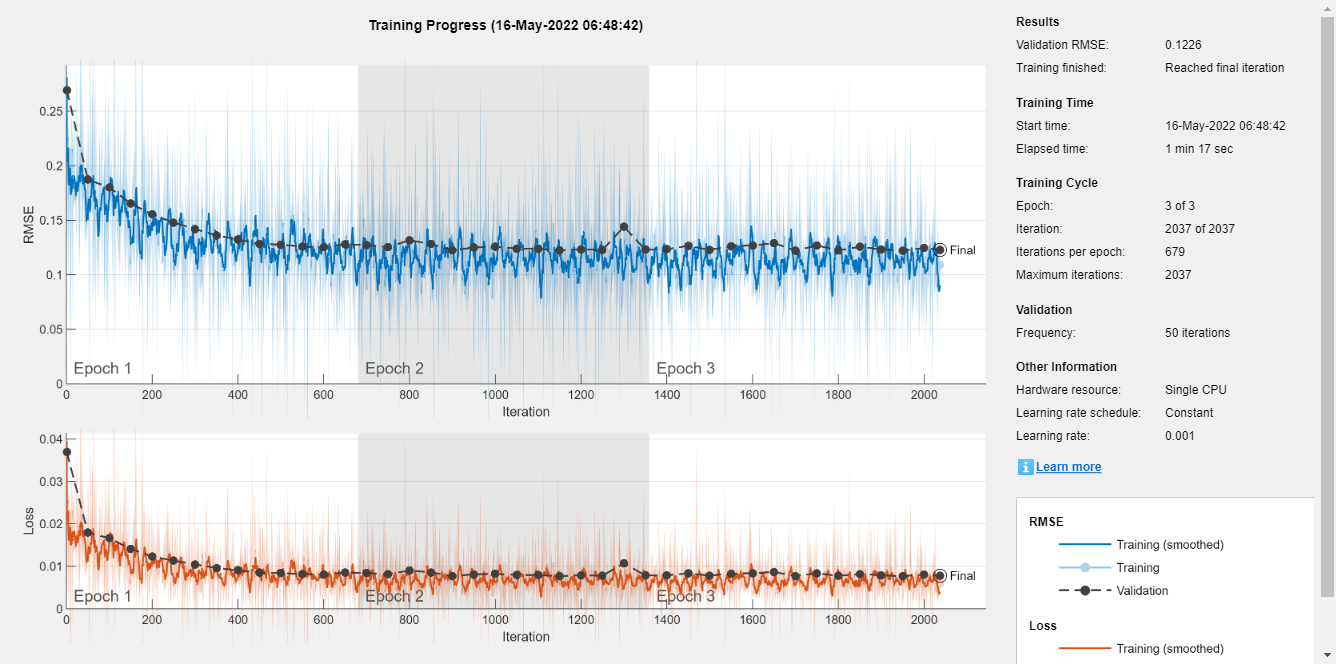

Elapsed time is 83.777843 seconds.



if generate_model
layersLSTM = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm_Ic_RUL', 1)';
cellyB = num2cell(ynorm_Ic_RUL);

traincellx = cellx(idxTrainAll, :);
valcellx = cellx(idxValidAll, :);
testcellx = cellx(idxTestAll, :);

traincellyB = cellyB(idxTrainAll, :);
valcellyB = cellyB(idxValidAll, :);
testcellyB = cellyB(idxTestAll, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',epoc_count_lstm, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

tic
netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);
toc 

tic
netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);
toc

save('ryan3_model_CC_RUL.mat','netLSTM' ,'-append')
save('ryan3_model_CC_RUL.mat','netLSTM2' ,'-append')

end


pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm_Ic_RUL(idxTestAll, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm_Ic_RUL(idxTestAll, :)', 1)));
ytest = ynorm_Ic_RUL(idxTestAll, :)*yrate_Ic_RUL + ymin_Ic_RUL;
pLSTM_hat = pLSTM * yrate_Ic_RUL + ymin_Ic_RUL;
pLSTM2_hat = pLSTM2 * yrate_Ic_RUL + ymin_Ic_RUL;
rmse_pLSTM_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM_hat = single
135.5862

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM2_hat = single
135.5862

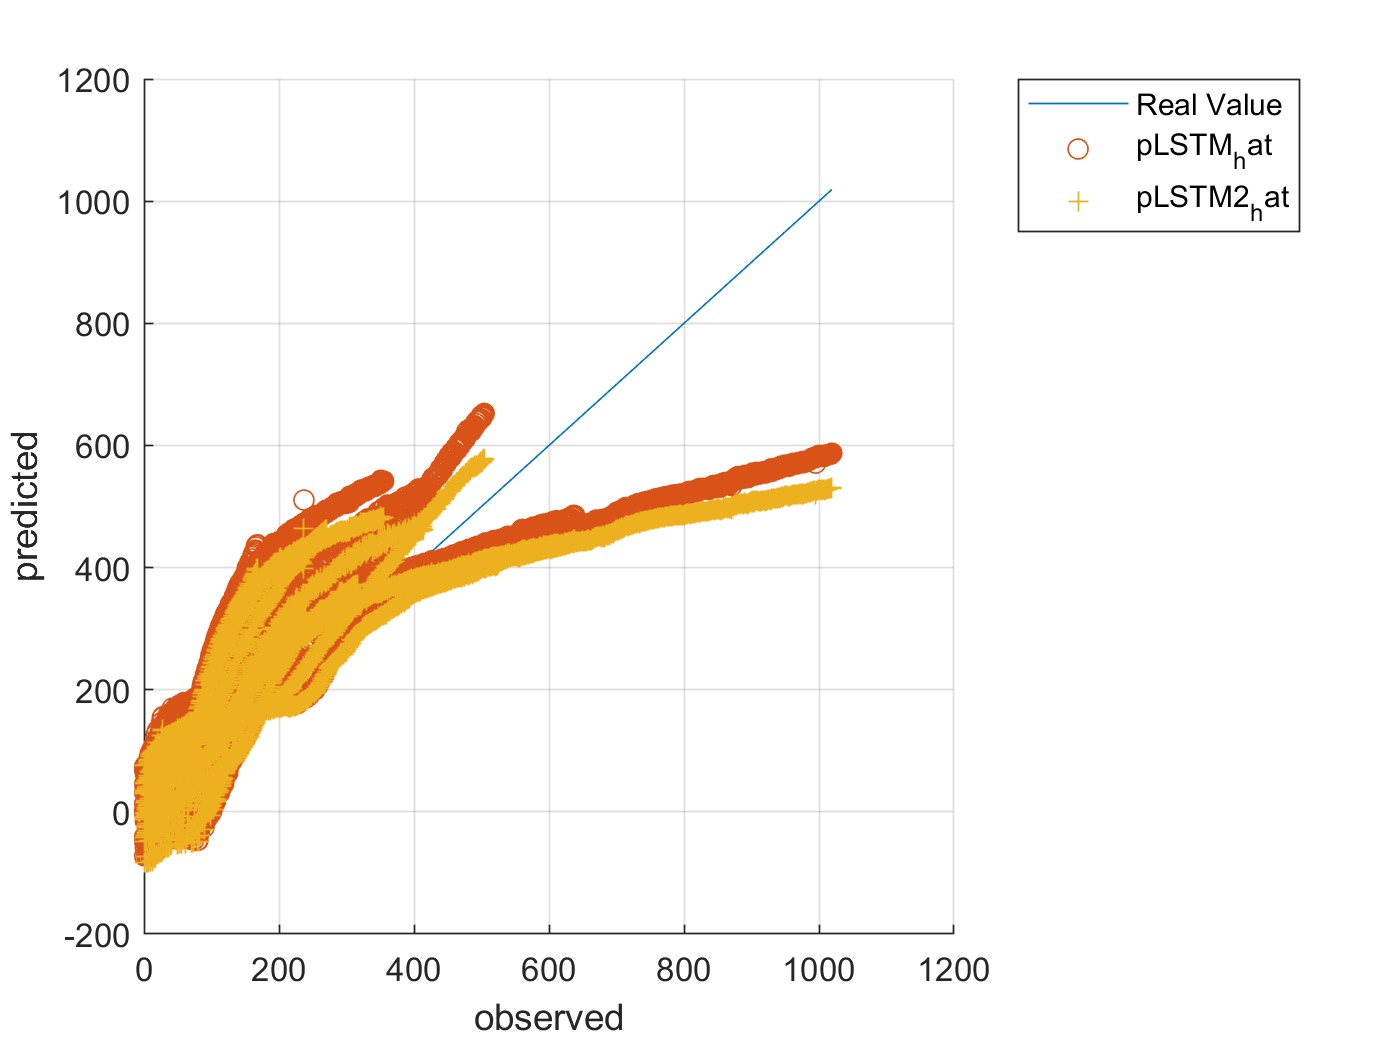



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_hat', ...
        'pLSTM2_hat','Location','northeastoutside')



pLSTM_self = cell2mat(predict(netLSTM, num2cell(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm_Ic_RUL([idxTrainAll idxValidAll], :)', 1)));
ytrain_self = ynorm_Ic_RUL([idxTrainAll idxValidAll], :)*yrate_Ic_RUL + ymin_Ic_RUL;
pLSTM_self = pLSTM_self * yrate_Ic_RUL + ymin_Ic_RUL;
pLSTM2_self = pLSTM2_self * yrate_Ic_RUL + ymin_Ic_RUL;
rmse_pLSTM_self_hat = sqrt(mean(( ytrain_self' - pLSTM_self' ).^2))

rmse_pLSTM_self_hat = single
130.8035

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
130.9548

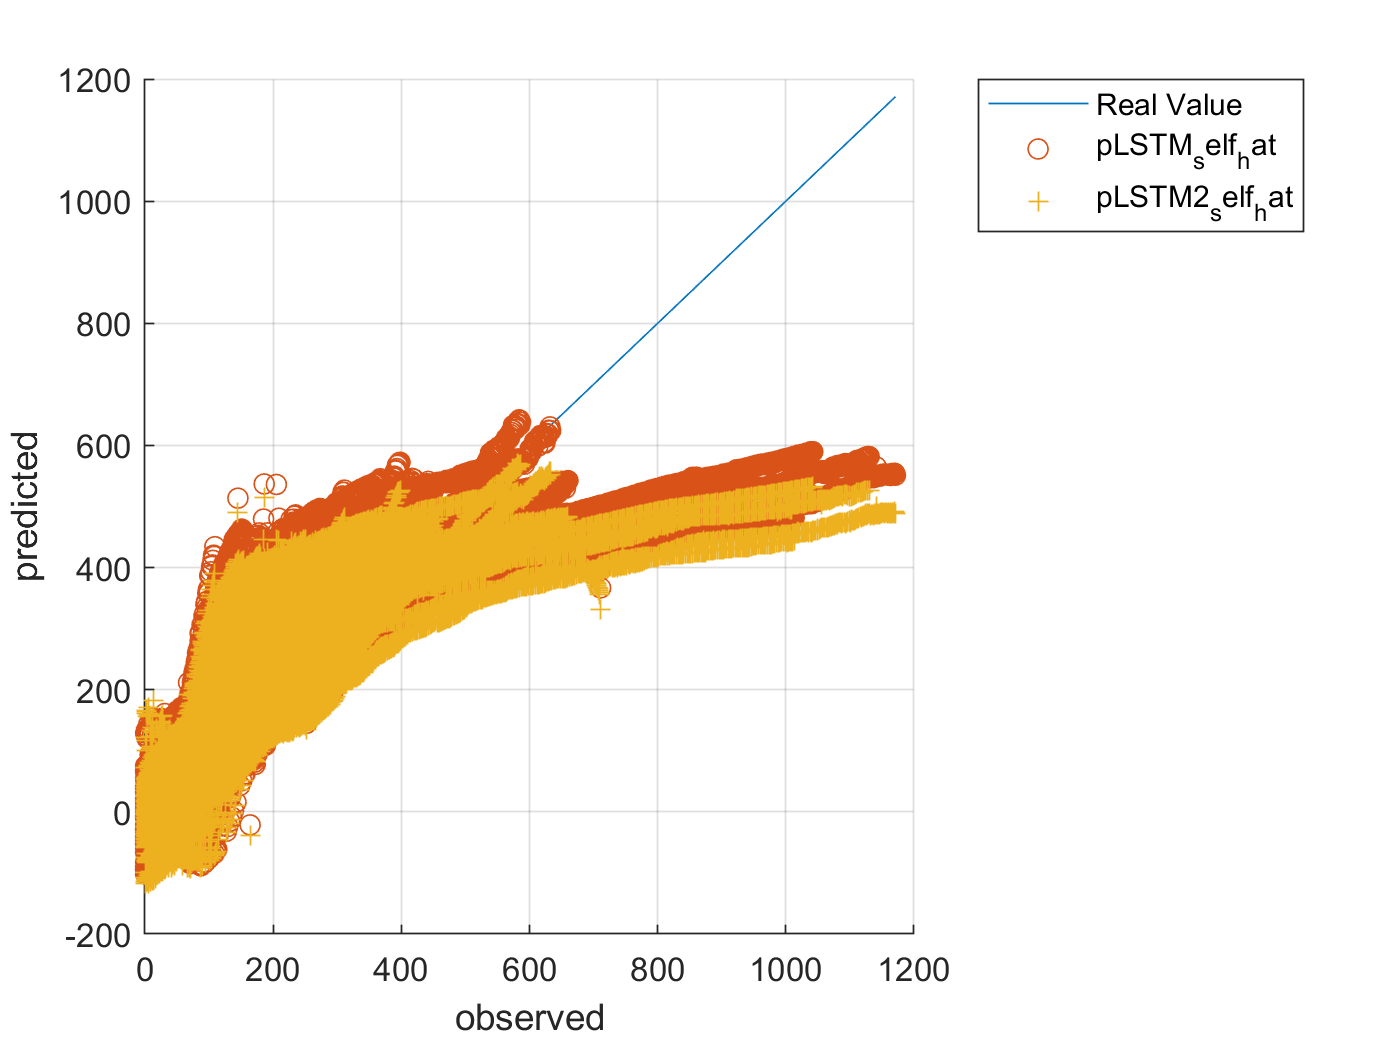


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')